# **Procesamiento de Imagenes Digitales**

## Taller 11.

Cargue la Imagen '`test_blur.jpg`' y visualicela (con titulo).

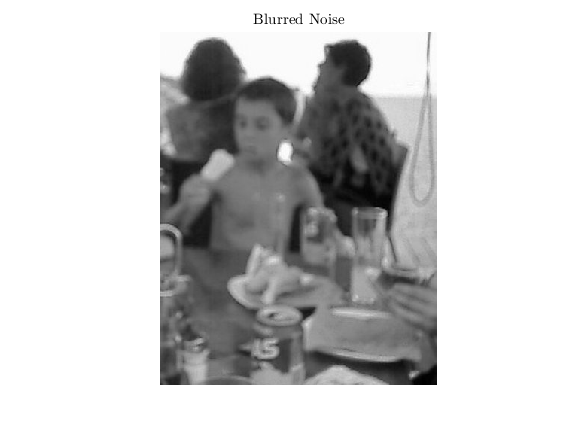

I = im2double(imread('test_blur.jpg'));
figure(1);
imshow(I,[]);title('Blurred Noise','interpreter','latex');

Genere la PSF inicial en un kernel $7\times 7$.

INITPSF = ones(7,7);

Genere una ventana para la región de operación en la iteración con un borde de 5 pixeles.

WT = zeros(size(I)); 
WT(6:end-5,6:end-5) = 1; 

Defina un umbral de amortiguación igual a 10 veces la varianza del ruido Gaussiano con $\sigma^{2} = 0.001, 0.01, 0.99.$

Var = [0.001, 0.01, 0.99];

Itere 5 veces y visualice las imagenes restauradas.

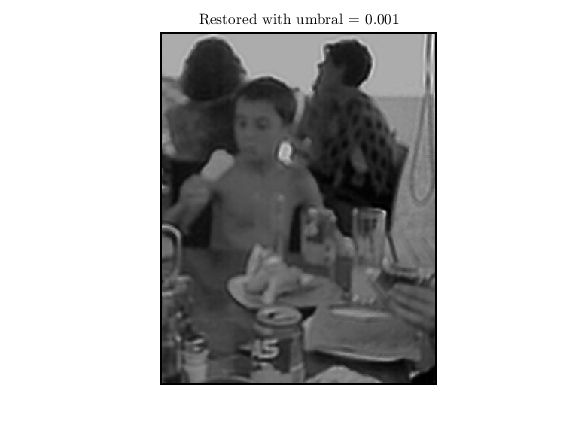

iter = 5;
[J1,P1] = deconvblind(I,INITPSF,iter,10*Var(1),WT);
[J2, P2] = deconvblind(I,INITPSF,iter,10*Var(2),WT);
[J3, P3] = deconvblind(I,INITPSF,iter,10*Var(3),WT);
figure(2);imshow(J1,[]);title('Restored with umbral = 0.001','interpreter','latex');

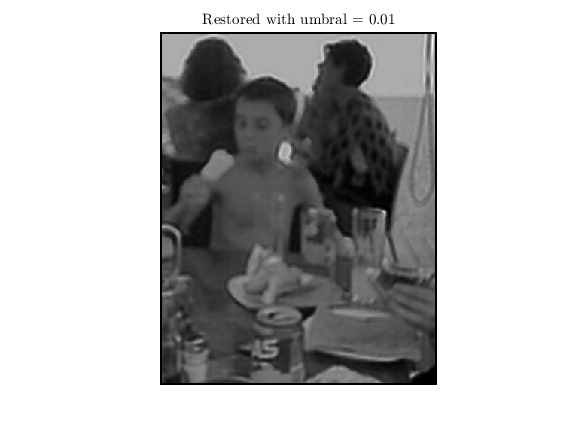

figure(3);imshow(J1,[]);title('Restored with umbral = 0.01','interpreter','latex');

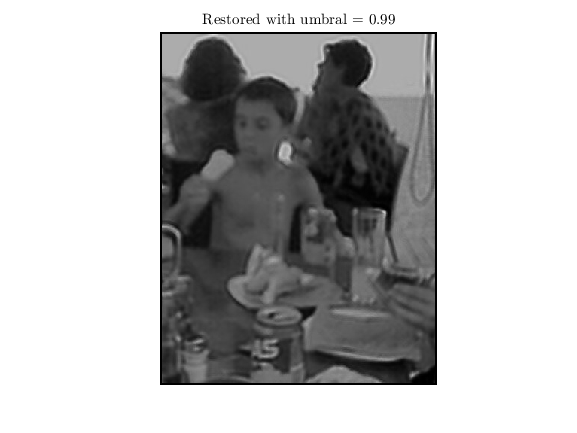

figure(4);imshow(J1,[]);title('Restored with umbral = 0.99','interpreter','latex');

De acuerdo con los resultados, construya y sisualice la PSF original. Tenga en cuenta que la desviación estandar del desenfoque es 1000 veces la varianza del ruido. 

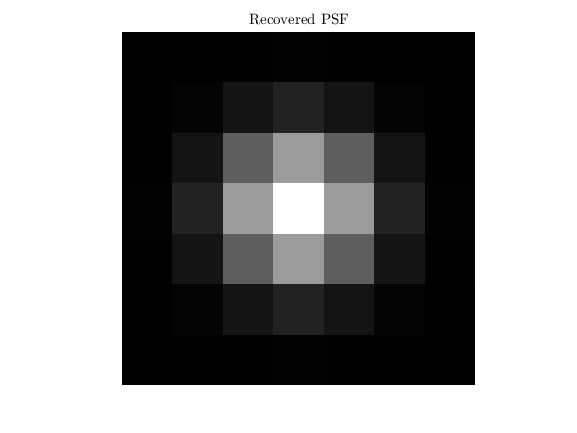

PSF = fspecial('gaussian', 7, 1000*Var(1));
figure;imshow(PSF,[],'InitialMagnification','fit');title('Recovered PSF','interpreter','latex');